 
clear
timerOverall = tic;
fprintf(['Beginning Script...' newline]);

Beginning Script...


[scenario, testName] = oblongTest;
video1 = false;
video2 = false;
video3 = false;

bounds = roadBoundaries(scenario);

outerBounds = flip(bounds{1}(:,1:2),1);
innerBounds = bounds{2}(:,1:2);
centers = horzcat(mean([innerBounds(:,1), outerBounds(:,1)],2),mean([innerBounds(:,2), outerBounds(:,2)],2));

centersDiff = [0; sqrt(sum((centers(2:end,:)-centers(1:end-1,:)).^2,2))];
sVals = cumsum(centersDiff);

normFactor = floor(sVals(end))/sVals(end);

centersNormalized = centers.*normFactor;
sValsNormalized = sVals.*normFactor;

waypoints = [spline(sValsNormalized, centersNormalized(:,1),0:sValsNormalized(end))',...
             spline(sValsNormalized, centersNormalized(:,2),0:sValsNormalized(end))'];

fprintf(['Beginning Optimization' newline])

Beginning Optimization


timeOptimization = tic;
[waypointsFit, videoSet, videoSetPt, sFit] = discreteWaypointOptimizer(waypoints, normFactor*3, 50, 0.01, 0.1, 0.2, testName);

Iteration: 1.000000 | k: 9.879162
Iteration: 2.000000 | k: 9.687928
Iteration: 3.000000 | k: 9.522862
Iteration: 4.000000 | k: 9.361602
Iteration: 5.000000 | k: 9.205201
Iteration: 6.000000 | k: 9.054502
Iteration: 7.000000 | k: 8.909627
Iteration: 8.000000 | k: 8.770759
Iteration: 9.000000 | k: 8.637803
Iteration: 10.000000 | k: 8.511151
Iteration: 11.000000 | k: 8.390940
Iteration: 12.000000 | k: 8.422679
Iteration: 13.000000 | k: 8.305597
Iteration: 14.000000 | k: 8.225237
Iteration: 15.000000 | k: 8.157562
Iteration: 16.000000 | k: 8.101173
Iteration: 17.000000 | k: 7.984692
Iteration: 18.000000 | k: 7.898843
Iteration: 19.000000 | k: 7.869703
Iteration: 20.000000 | k: 7.801203
Iteration: 21.000000 | k: 7.756318
Iteration: 22.000000 | k: 7.672496
Iteration: 23.000000 | k: 7.587046
Iteration: 24.000000 | k: 7.549816
Iteration: 25.000000 | k: 7.527642
Iteration: 26.000000 | k: 7.505113
Iteration: 27.000000 | k: 7.480946
Iteration: 28.000000 | k: 7.458230
Iteration: 29.000000 | k: 7.4

timeOptimizationOut = toc(timeOptimization);
fprintf(['Optimization Complete: %f sec' newline],timeOptimizationOut);

Optimization Complete: 98.157568 sec


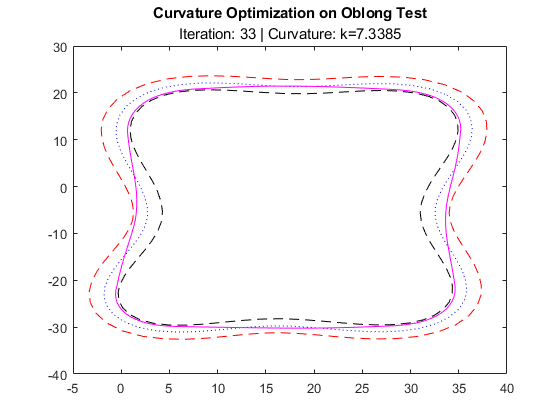


videoSet(:,1) = cellfun(@(x) x/normFactor, videoSet(:,1), 'un',0);
videoSetPt(:,1) = cellfun(@(x) x/normFactor, videoSetPt(:,1), 'un',0);

videoSet(:,3) = cellfun(@(x) x/normFactor, videoSet(:,3), 'un',0);
videoSetPt(:,3) = cellfun(@(x) x/normFactor, videoSetPt(:,3), 'un',0);

waypointsFit = waypointsFit./normFactor;

[velocityProfile, minTLap] = velocityProfiler(0.001, [waypointsFit(1:end-1,:); waypointsFit(1:end-1,:); waypointsFit(:,:)], sFit, 4*300, 0.5*300, 300);
iterationEnd = videoSet{end,2};
curvatureEnd = videoSet{end,3};


if video1
    fprintf(['Beginning Video Output By Iteration...' newline]);
    timeVideo1 = tic;
    writer1(videoSet, testName, centers, innerBounds, outerBounds);
    timeVideo1Out = toc(timeVideo1);
    fprintf(['Video 1 Complete: %f sec' newline],timeVideo1Out);
end

if video2
    fprintf(['Beginning Video Output By Point...' newline])
    timeVideo2 = tic
    writer2(videoSetPt, testName, centers, innerBounds, outerBounds);
    timeVideo2Out = toc(timeVideo2);
    fprintf(['Video 2 Complete: %f sec' newline],timeVideo2Out);
end

if video3
    fprintf(['Beginning Video Output By Velocity...' newline])
    timeVideo3 = tic
    writer3(velocityProfile, 40, testName, waypointsFit, innerBounds, outerBounds, minTLap, iterationEnd, curvatureEnd);
    timeVideo3Out = toc(timeVideo3);
    fprintf(['Velocity Video Complete: %f sec' newline],timeVideo3Out);
end


if ~video1 && ~video2 && ~video3
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        waypointsFit(:,1), waypointsFit(:,2), 'm',...
        'Visible',"on");
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{end,2}),' | Curvature: k=',num2str(videoSet{end,3})]);
end


fprintf(['Script Complete: %f sec' newline], toc(timerOverall))

Script Complete: 99.739544 sec


function writer1(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter(testName(testName ~= ' '));
writer.FrameRate = 1;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer2(videoSet, testName, centers, innerBounds, outerBounds)
writer = VideoWriter([testName(testName ~= ' '),'ByPt']);
writer.FrameRate = 60;
open(writer);
for idxVidSet = 1:size(videoSet,1)
    plot(centers(:,1), centers(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), '--k',...
        innerBounds(:,1), innerBounds(:,2), '--r',...
        videoSet{idxVidSet,1}(:,1), videoSet{idxVidSet,1}(:,2), 'm',...
        'Visible',"on");
    hold on
    plot(videoSet{idxVidSet,4}(1), videoSet{idxVidSet,4}(2),'*m');
    title(['Curvature Optimization on ',testName],['Iteration: ',num2str(videoSet{idxVidSet,2}),' | Curvature: k=',num2str(videoSet{idxVidSet,3})]);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

function writer3(videoSet, fps, testName, minCurPath, innerBounds, outerBounds, minTLap, itEnd, kEnd)
writer = VideoWriter([testName(testName ~= ' '),'ByVel']);
writer.FrameRate = fps;
skipFactor = (1/fps)*(1/(videoSet(2,2)-videoSet(1,2)));
open(writer);
for idxVidSet = 1:skipFactor:size(videoSet,1)
    plot(minCurPath(:,1), minCurPath(:,2), ':b',...
        outerBounds(:,1), outerBounds(:,2), 'r',...
        innerBounds(:,1), innerBounds(:,2), 'r',...
        videoSet(idxVidSet,4), videoSet(idxVidSet,5), 'mo',...
        'Visible',"on");
    hold on
    title(['Velocity Optimization on Minimum Curvature Path for ',testName],['Iteration: ',num2str(itEnd,'%.0f'),' | Curvature: k=',num2str(kEnd),'[1/m] | Minimum Lap Time t=',num2str(minTLap,'%.3f'),'[s]', newline,'Time: t=',num2str(videoSet(idxVidSet,2),'%.3f'),'[s] | Velocity: v=',num2str(videoSet(idxVidSet,1),'%.3f'), '[m/s]']);
    xlabel('X [m]');
    ylabel('Y [m]');
    axis equal
    hold off
    writeVideo(writer,getframe(gcf));
end
close(writer);
end

% [ai] a(v=0) = 0
% [av] a(v=20) = 3
% [am] a(v=40) = 6
% da/dv = ra((am-a)/am)
% da/dt max = 2
% dv/dt max = 5
% dp/dt max = 40
% a = am/(1+be^(-kv))
% 